# 3.5

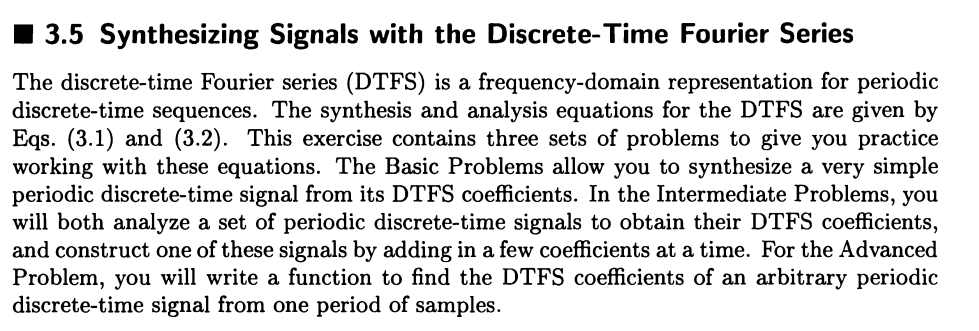

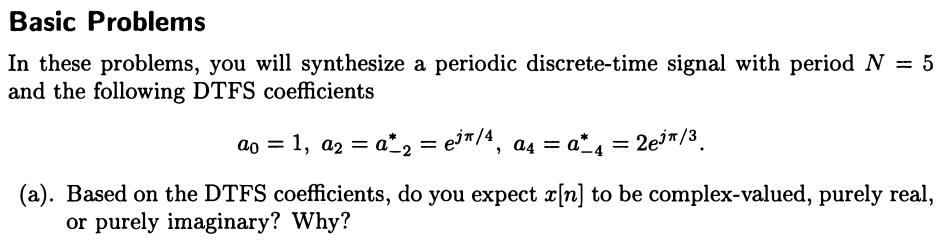

It's purly real. Because compute x[n] using dtfs on range [-2 2]. a_1 =  a_{-4}. a_{-1} = a_{4}. So a_1 and a_{-1} are conjugate too. So there are two conjugate pairs  and real number of component of a0. So it's real.

a1 = $a_{1-5}$ simliar for a3.

close('all'); clear; clc;
a = [1, 2*exp(-1i*pi/3), exp(1i*pi/4), exp(-1i*pi/4), 2*exp(1i*pi/3)];

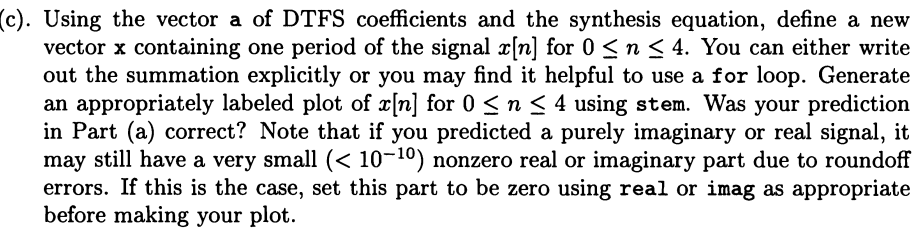

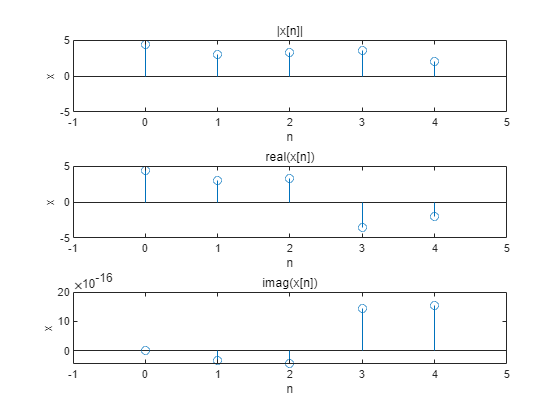

close('all'); clear; clc;
a = [1, 2*exp(-1i*pi/3), exp(1i*pi/4), exp(-1i*pi/4), 2*exp(1i*pi/3)];
[k n] = meshgrid(0:20, 0:4);
kn = k.*n;
ex = exp(1i*2*pi/5.*kn);
x = a*ex;

f35c = figure; figure(f35c);
subplot(3,1,1);
stem(0:4, abs(x(1:5))); axis([-1 5 -5 5]);
title('|x[n]|'); xlabel('n'); ylabel('x');
subplot(3,1,2);
stem(0:4, real(x(1:5))); axis([-1 5 -5 5]);
title('real(x[n])'); xlabel('n'); ylabel('x');
subplot(3,1,3);
stem(0:4, imag(x(1:5))); axis([-1 5 ylim])
title('imag(x[n])'); xlabel('n'); ylabel('x');

Prediction in Part(a) is correct. It's real. The imaginary part is less than $10^{-10}$.

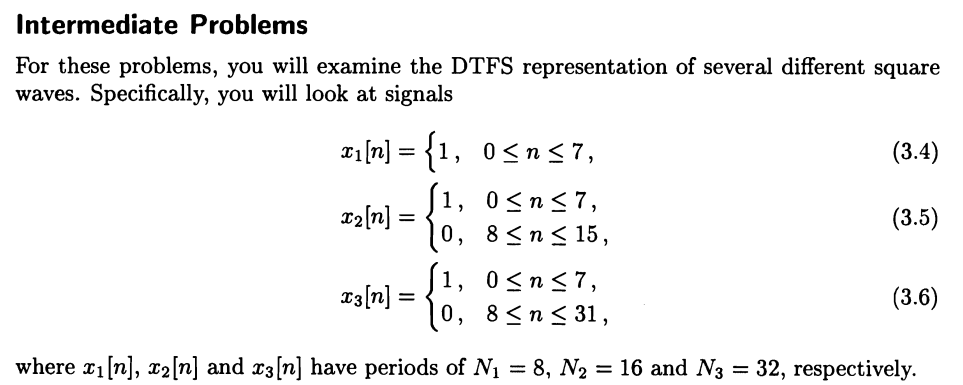

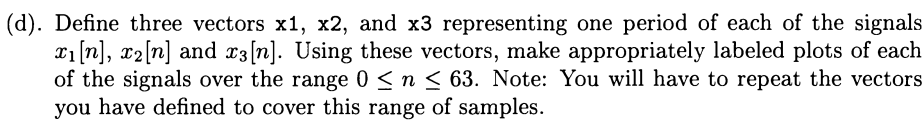

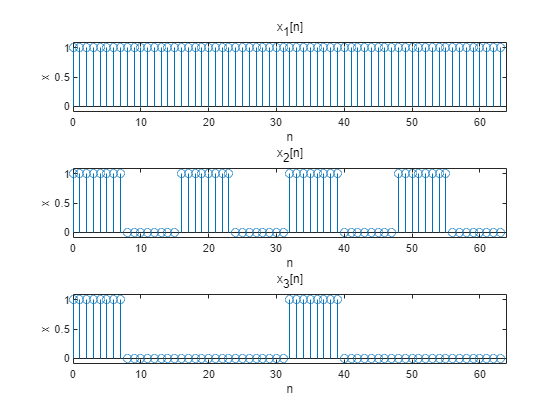

close('all'); clear; clc;
n = 0:63;

s1 = [ones(1,8)];
s2 = [ones(1,8) zeros(1,8)];
s3 = [ones(1,8) zeros(1,24)];

x1 = repmat(s1, 1, length(n)/length(s1));
x2 = repmat(s2, 1, length(n)/length(s2));
x3 = repmat(s3, 1, length(n)/length(s3));

f35d = figure;
figure(f35d);
subplot(3,1,1);
stem(n, x1); axis([0 64 -0.1 1.1]);
title('x_1[n]'); xlabel('n'); ylabel('x');
subplot(3,1,2);
stem(n, x2); axis([0 64 -0.1 1.1]);
title('x_2[n]'); xlabel('n'); ylabel('x');
subplot(3,1,3);
stem(n, x3); axis([0 64 -0.1 1.1]);
title('x_3[n]'); xlabel('n'); ylabel('x');

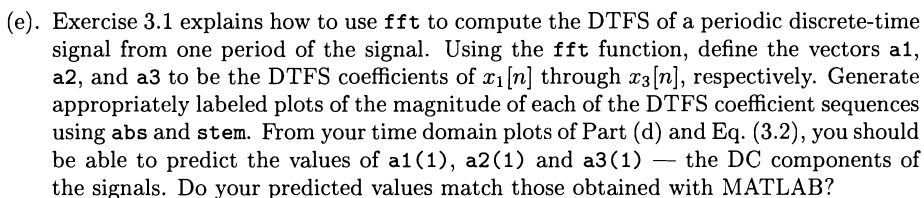

a(1 ) is equal to sum of a period of the discrete signal and then divide it use T.

a1(1) = 8/8 =1 ; a2(1) = 8/16 = 0.5; a3(1) = 8/32 =0.25;

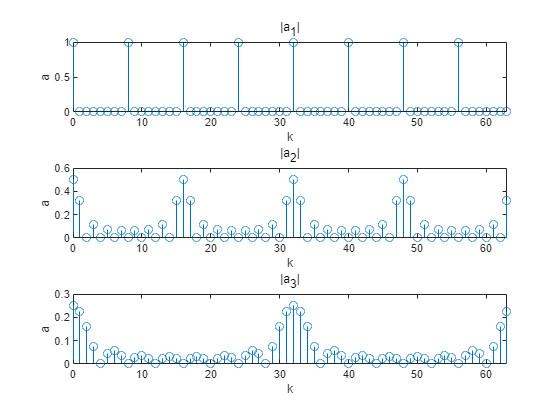

close('all'); clear; clc;
n = 0:63;

s1 = [ones(1,8)];
s2 = [ones(1,8) zeros(1,8)];
s3 = [ones(1,8) zeros(1,24)];

a1 = fft(s1)/length(s1);
a2 = fft(s2)/length(s2);
a3 = fft(s3)/length(s3);

a1 = repmat(a1, 1, length(n)/length(a1));
a2 = repmat(a2, 1, length(n)/length(a2));
a3 = repmat(a3, 1, length(n)/length(a3));

figure;
subplot(3,1,1);
stem(n, abs(a1)); axis([0 63 ylim]); 
title('|a_1|'); xlabel('k'); ylabel('a');
subplot(3,1,2);
stem(n, abs(a2)); axis([0 63 ylim]); 
title('|a_2|'); xlabel('k'); ylabel('a');
subplot(3,1,3);
stem(n, abs(a3)); axis([0 63 ylim]); 
title('|a_3|'); xlabel('k'); ylabel('a');

a1(1)

ans = 1

a2(1)

ans = 0.5000

a3(1)

ans = 0.2500

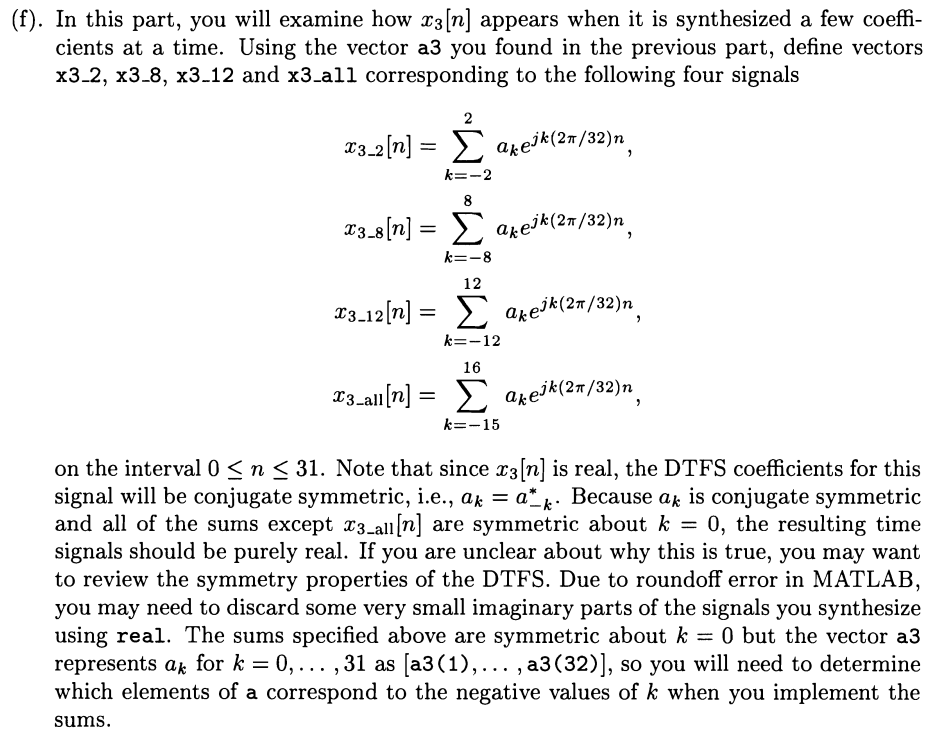

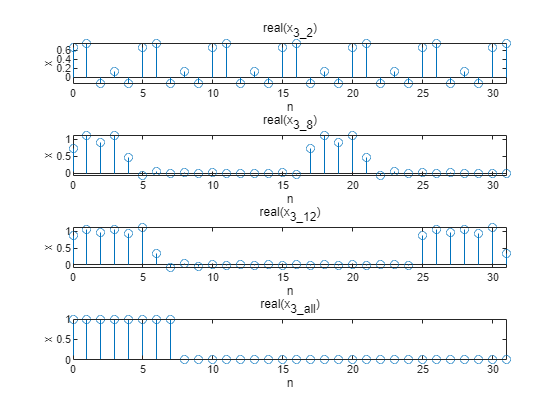

close('all'); clear; clc;
s3 = [ones(1,8) zeros(1,24)];
a3 = fft(s3)/length(s3);
a3 = repmat(a3, 1, 2);
a3_sft = fftshift(a3);

n = 0:63;
mid = length(n)/2 + 1;
a3_2 = a3_sft(mid-2:mid+2);
a3_8 = a3_sft(mid-8:mid+8);
a3_12 = a3_sft(mid-12:mid+12);
a3_all = a3_sft(mid-15:mid+16);

n = 0:31;
x3_2 = a3_2 * exp( 1i*2*pi/length(a3_2) * (-2:2).' * n );
x3_8 = a3_8 * exp( 1i*2*pi/length(a3_8) * (-8:8).' * n );
x3_12 = a3_12 * exp( 1i*2*pi/length(a3_12) * (-12:12).' * n );
x3_all = a3_all * exp( 1i*2*pi/length(a3_all) * (-15:16).' * n );

f35f = figure;
figure(f35f);
subplot(4,1,1);
stem(n, real(x3_2)); 
axis([0 31 ylim]);
title('real(x_{3\_2})'); xlabel('n'); ylabel('x');
subplot(4,1,2);
stem(n, real(x3_8));
axis([0 31 ylim]);
title('real(x_{3\_8})'); xlabel('n'); ylabel('x');
subplot(4,1,3);
stem(n, real(x3_12)); 
axis([0 31 ylim]);
title('real(x_{3\_12})'); xlabel('n'); ylabel('x');
subplot(4,1,4);
stem(n, real(x3_all)); 
axis([0 31 ylim]);
title('real(x_{3\_all})'); xlabel('n'); ylabel('x');

close('all'); clear; clc;
s3 = [ones(1,8) zeros(1,24)];
a3 = fft(s3)/length(s3);
a3 = repmat(a3, 1, 2);
a3_sft = fftshift(a3);

n = 0:63;
mid = length(n)/2 + 1;
an = 1;
for i=1:15
    an = an && (a3(mid-i) == a3(mid+i)');
end
an

an = logical
   1


a3(mid+16)

ans = 0

for i<=15 a3_i = a3_{-i}* so the sum of these corresponding component is real.

what's more a3_16 = 0. So the result is real.

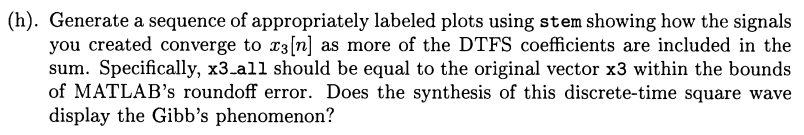

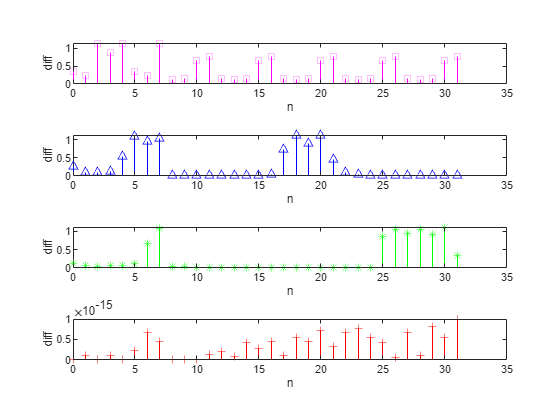

close all; clear; clc;
s3 = [ones(1,8) zeros(1,24)];
a3 = fft(s3)/length(s3);
a3 = repmat(a3, 1, 2);
a3_sft = fftshift(a3);

n = 0:63;
mid = length(n)/2 + 1;
a3_2 = a3_sft(mid-2:mid+2);
a3_8 = a3_sft(mid-8:mid+8);
a3_12 = a3_sft(mid-12:mid+12);
a3_all = a3_sft(mid-15:mid+16);

n = 0:31;
x3_2 = a3_2 * exp( 1i*2*pi/length(a3_2) * (-2:2).' * n );
x3_8 = a3_8 * exp( 1i*2*pi/length(a3_8) * (-8:8).' * n );
x3_12 = a3_12 * exp( 1i*2*pi/length(a3_12) * (-12:12).' * n );
x3_all = a3_all * exp( 1i*2*pi/length(a3_all) * (-15:16).' * n );

f35h = figure; 
figure(f35h)

subplot(4,1,1);
stem(n, abs(real(s3)-real(x3_2)),'ms');
xlabel('n'); ylabel('diff');


subplot(4,1,2)
stem(n, abs(real(s3)-real(x3_8)),'b^'); 
xlabel('n'); ylabel('diff');


subplot(4,1,3);
stem(n, abs(real(s3)-real(x3_12)),'g*');
xlabel('n'); ylabel('diff');


subplot(4,1,4);
stem(n, abs(real(s3)-real(x3_all)),'r+');
xlabel('n'); ylabel('diff');

The diff between x3_all and x3 is smaller than 10^{-10}.

The synthesis shows the Gibb's phenomenon. The  oscillatory behaviour of generated signal around n=7 becomes smaller as more components added.

# 3.8

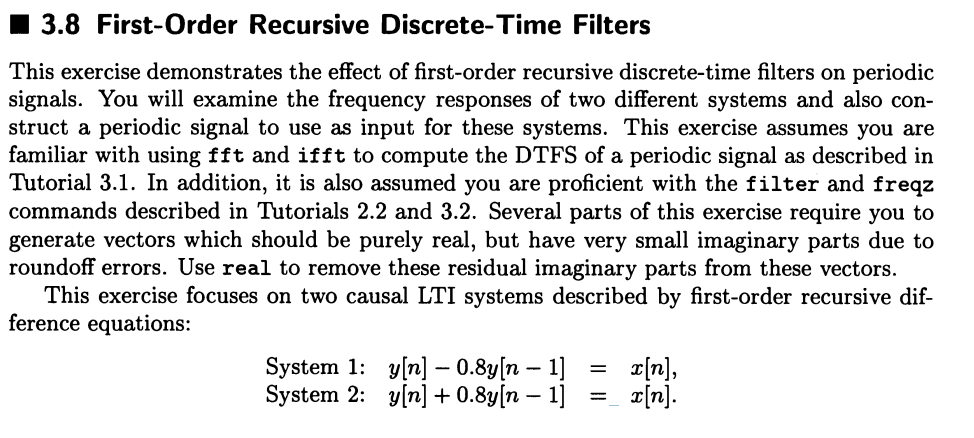

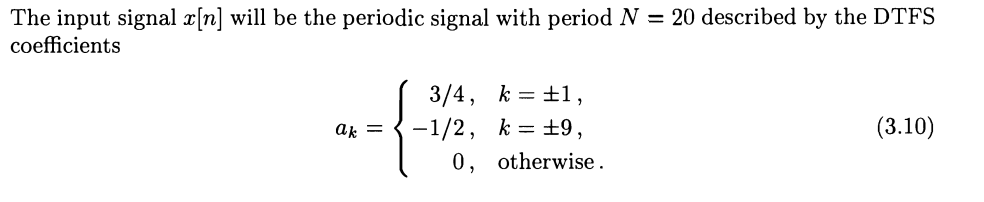

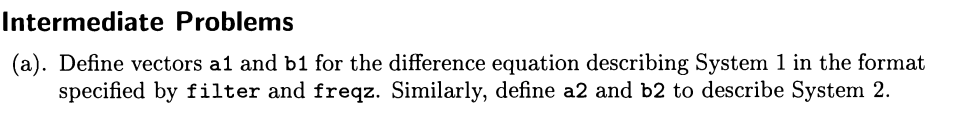

close('all'); clear; clc;
a1 = [1 -0.8];
b1 = 1;
a2 = [1 0.8];
b2 = 1;

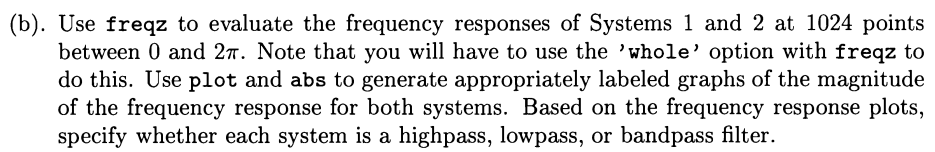

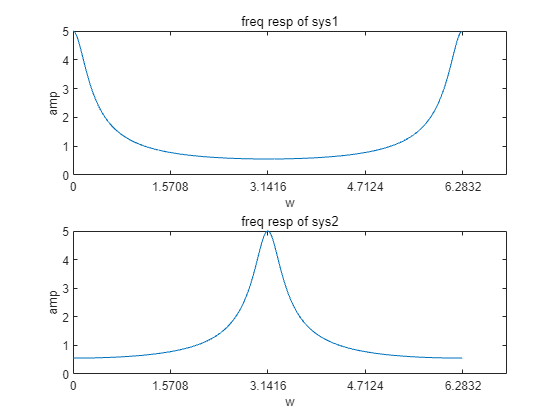

close('all'); clear; clc;
a1 = [1 -0.8];
b1 = 1;
a2 = [1 0.8];
b2 = 1;
[H1, w1] = freqz(b1, a1, 1024, 'whole');
[H2, w2] = freqz(b2, a2, 1024, 'whole');
f38b = figure;
figure(f38b);
subplot(2,1,1);
plot(w1, abs(H1));
set(gca, 'xtick',0:pi/2:2*pi);
xlabel('w');
ylabel('amp');
title('freq resp of sys1');
subplot(2,1,2);
plot(w2, abs(H2));
set(gca, 'xtick',0:pi/2:2*pi);
xlabel('w');
ylabel('amp');
title('freq resp of sys2');

sys1 is highpass and lowpass. sys2 is bandpass.

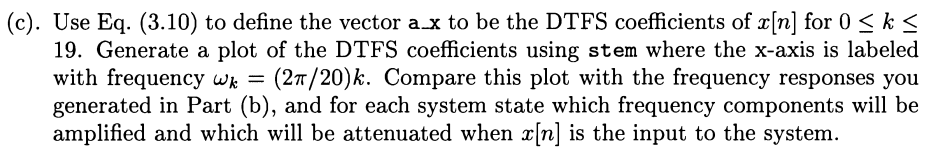

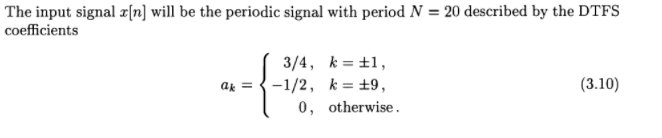

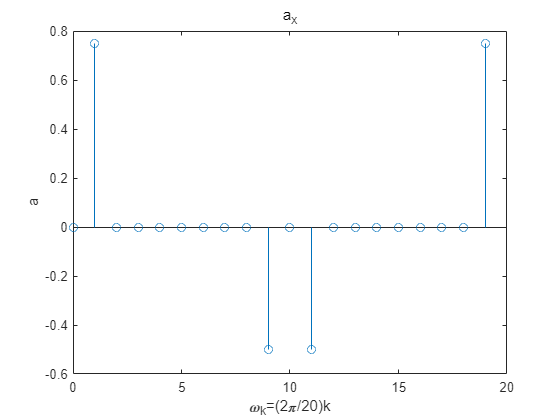

close('all'); clear; clc;
a_x = [0 3/4 zeros(1,7) -1/2 0 -1/2 zeros(1,7) 3/4];
f38c = figure;figure(f38c);
stem(0:19, a_x);
title('a_x'); xlabel('\omega_k=(2\pi/20)k'); ylabel('a');

Through system 1, the components of k=1  and 19 will be amplified and components of k=9 and 11 will be attenuated.

Through system 2, the components of k=9  and 11 will be amplified and components of k=1 and 19 will be attenuated.

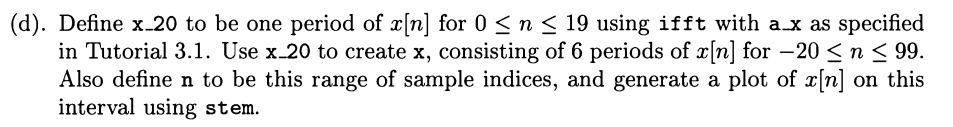

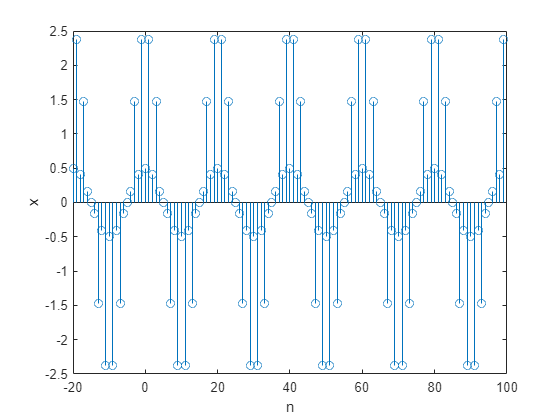

close('all'); clear; clc;
a_x = [0 3/4 zeros(1,7) -1/2 0 -1/2 zeros(1,7) 3/4];
x_20 = ifft(a_x)*length(a_x);
x = repmat(x_20, 1, 6);
n = -20:99;

f38d = figure; figure(f38d);
stem(n, x);
xlabel('n'); ylabel('x');

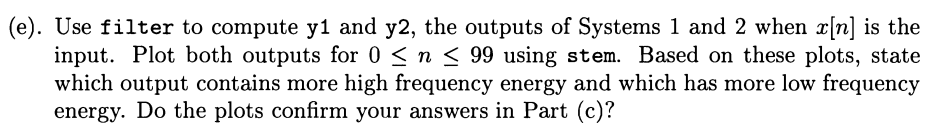

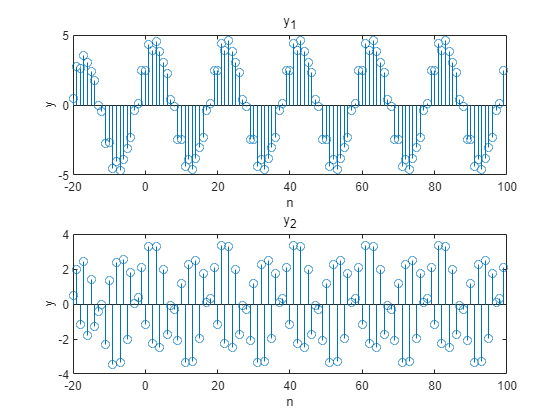

close('all'); clear; clc;
a_x = [0 3/4 zeros(1,7) -1/2 0 -1/2 zeros(1,7) 3/4];
x_20 = ifft(a_x)*length(a_x);
x = repmat(x_20, 1, 6);
n = -20:99;

a1 = [1 -0.8]; b1 = 1;
a2 = [1 0.8]; b2 = 1;

y1 = filter(b1, a1, x);
y2 = filter(b2, a2, x);

f38e = figure(); figure(f38e);
subplot(2,1,1);
stem(n, y1); 
title('y_1'); xlabel('n'); ylabel('y');
subplot(2,1,2);
stem(n, y2); 
title('y_2'); xlabel('n'); ylabel('y');

y1 is denser, so it's has more high freqency energy. In contrast, y2 has more low frequency energy.

As sys1 is lowpass and highpass and sys2 is bandpass. This confirms the answers in part(c).

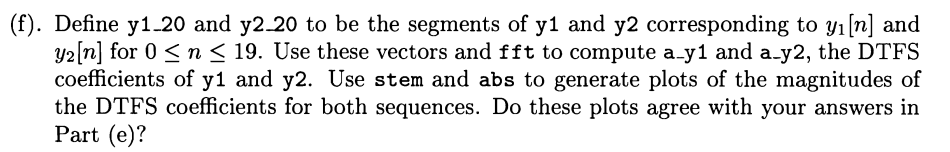

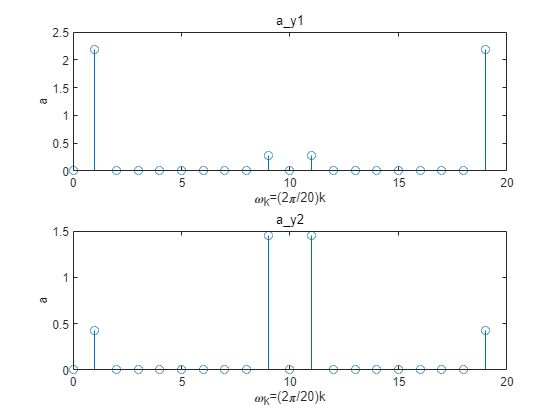

close('all'); clear; clc;
a_x = [0 3/4 zeros(1,7) -1/2 0 -1/2 zeros(1,7) 3/4];
x_20 = ifft(a_x)*length(a_x);
x = repmat(x_20, 1, 6);
n = -20:99;

a1 = [1 -0.8]; b1 = 1;
a2 = [1 0.8]; b2 = 1;

y1 = filter(b1, a1, x);
y2 = filter(b2, a2, x);

y1_20 = y1(21:40);
y2_20 = y2(21:40);
a_y1 = fft(y1_20)./20;
a_y2 = fft(y2_20)./20;

f38f = figure; figure(f38f);
subplot(2,1,1);
stem(0:19, abs(a_y1));
title('a\_y1'); xlabel('\omega_k=(2\pi/20)k'); ylabel('a');
subplot(2,1,2);
stem(0:19, abs(a_y2)); 
title('a\_y2'); xlabel('\omega_k=(2\pi/20)k'); ylabel('a');

The a_x gets gain of H1 or H2 after x goes througn sys1 and sys2. The a_y1 is larger when k is close to 0 and 20. And the a_y2 is larger when k is close to 10. y1 has more high frequency energy and y2 has more low frequency energy. So these plots agree with the answers in part(e).